# Panda APF Secondary

clear
close all

## Grid

grid = OctoGrid(2,2,2,100);

% add column
grid.addBox(1.25,0.9,0,0.2,0.2,1.5)
% add wall
grid.addBox(0.6,0.8,0,0.8,0.1,1.5)

## Generate a list of transformations

transformations_list = getPartialTransformationsListPanda('points_per_segment', 1*[1 1 1 1 1 1 1])

## Generate goal points

% trajectory generation points (xyz position, xyz angles)
control_points = [1.088 1 0.926 0 0 0;
                  1.4 1.2 0.5 0 0 0]; 

% robot base transformation (move to x - 1m, y - 1m)
Tbase = eye(4);
Tbase(1:2,4) = [1 1]';

## Calculate field

% Attractive
[grid_attractive] = attractive_field_3D(grid.grid, control_points(2,1:3), grid.resolution);

% Repulsive
kernel_size = 50; % how far should obstacles exert effect
sigma = 25 ; % how quickly should effect exerted by obstacles fall

[grid_repulsive] = convolution_offline_3D(grid.grid,kernel_size,sigma);

% Total
Ka = 10; % attractive field coefficient
Kr = -5; % repulsive field coefficient

% total field is a weighted sum of both
grid_total_field = Ka * grid_attractive + Kr * grid_repulsive;

## Calculate trajectory

% [joints_positions_APF, EE_positions_APF, goal_distances_APF, q_velocities_APF, ee_velocities_APF, values_APF] = APF_trajectory_closestPoint(grid_total_field, grid_repulsive, grid.resolution, control_points(2,1:3), Tbase, zeros(7,1),'avoid_task',true);
% [joints_positions_APF, EE_positions_APF, goal_distances_APF, q_velocities_APF, ee_velocities_APF, values_APF] = APF_trajectory_EEandOnePoint(grid_total_field, grid_repulsive, grid.resolution, control_points(2,1:3), Tbase, zeros(7,1),'avoid_task',true, 'mid_joints', true);

% EE + Joint 4 Wall Constant Repulsive Force for j4(dy = 0.2)
[joints_positions_APF, EE_positions_APF, goal_distances_APF, q_velocities_APF, ee_velocities_APF, values_APF] = APF_trajectory_EEandOnePointSimpleWallDistance(grid_total_field, grid_repulsive, grid.resolution, control_points(2,1:3), Tbase, zeros(7,1),'avoid_task',true, 'mid_joints', true);

% EE Only, no Repulsive Force
[joints_positions_APF_f, EE_positions_APF_f, goal_distances_APF_f, q_velocities_APF_f, ee_velocities_APF_f, values_APF_f] = APF_trajectory_EEandOnePointSimpleWallDistance(grid_total_field, grid_repulsive, grid.resolution, control_points(2,1:3), Tbase, zeros(7,1),'avoid_task',false, 'mid_joints', true);

## Open movement display

showMovementPanda(grid, grid_repulsive, control_points, joints_positions_APF, EE_positions_APF, values_APF, Tbase)

ans =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


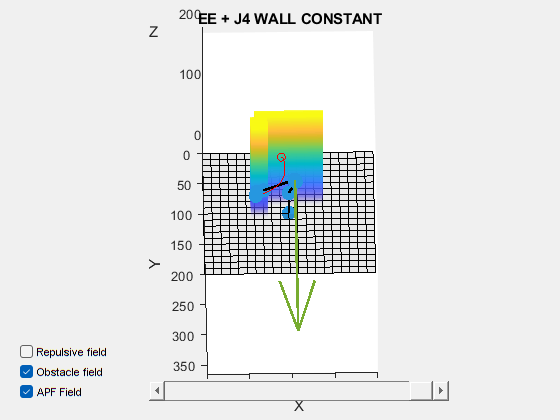

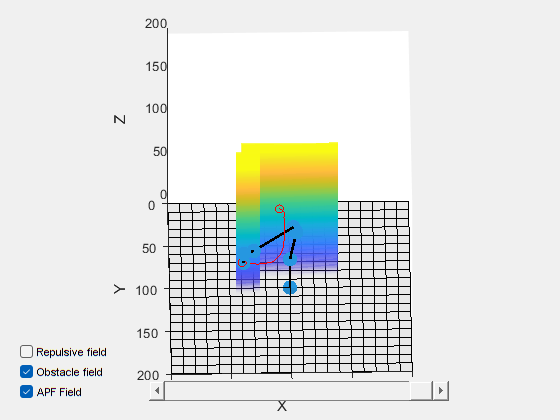

Index exceeds the number of array elements.
Index must not exceed 0.

Error in showMovementPanda (line 102)
    for i = 1:1:size(values_APF(1).xyz,1)        

showMovementPanda(grid, grid_repulsive, control_points, joints_positions_APF_f, EE_positions_APF_f, values_APF_f, Tbase)